# Simulink Workspace

close all;
clear all;

simulation_dt = 0.001;
controller_dt = 0.001;

k_harmonics = 7;

model.delta = 0.2;    % damping
model.alpha = -1;     % linear stiffness
model.beta  = 1;      % nonlinear stiffness

colors = get(groot, 'defaultAxesColorOrder');

to2D = @(vec) [vec(2:k_harmonics+1), vec(k_harmonics+2:end)];
getMag = @(vec) sum(sqrt(vec(:, 1).^2 + vec(:, 2).^2), "all");

num_tests = 21;

target_amplitudes = linspace(0.05, 2, num_tests);
fundamental_frequencies = linspace(0.2, 0.4, num_tests);


input.fundamental_frequency = 0.3;
input.A_vec = zeros(k_harmonics, 1);
input.B_vec = zeros(k_harmonics, 1);
input.target_amplitude = 2;
input.B_vec(1) = input.target_amplitude;
input.coeffs = @(struct) [0; struct.A_vec; struct.B_vec];

## Open Loop

% open_model = 'model4';
% input.fundamental_frequency = fundamental_frequencies(5);
% for i = (1:num_tests)
%     input.target_amplitude = target_amplitudes(i);
%     open_simOut = sim(open_model);
% end

## CBC S-curve

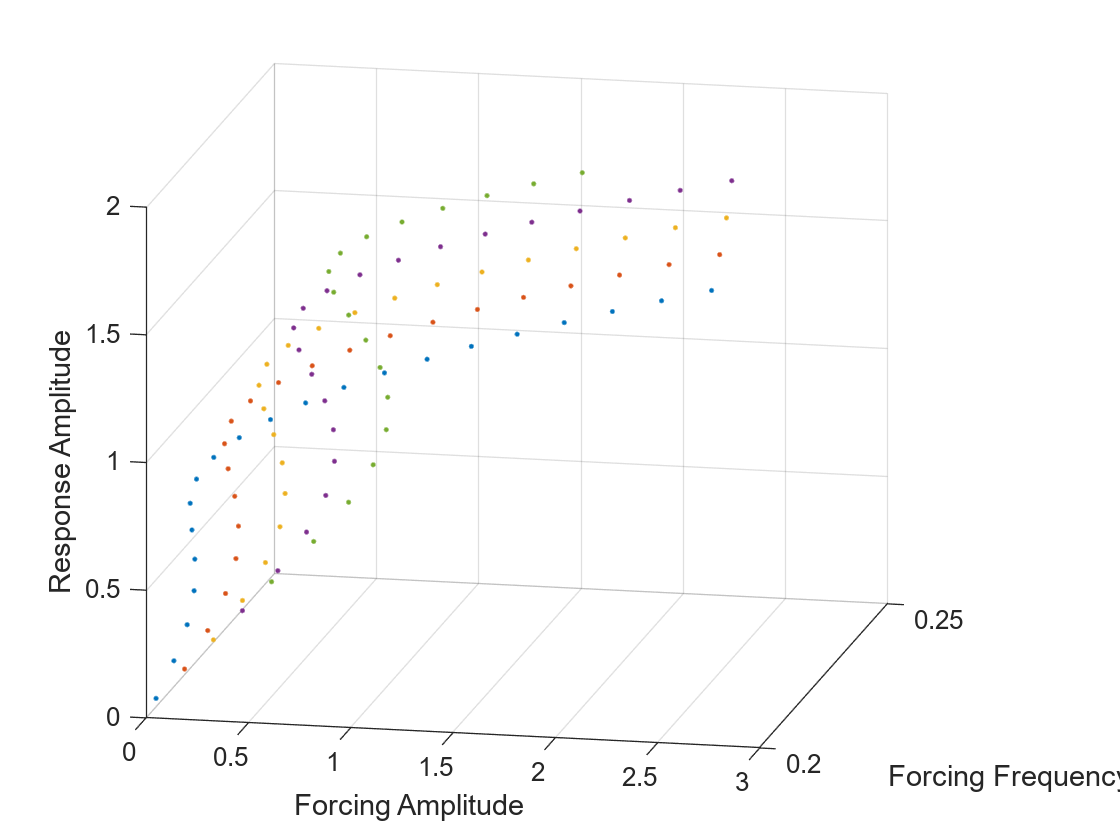

% Name of your model
simulink_model = 'model3';



fc_history = zeros(2*k_harmonics+1, num_tests, num_tests);
rc_history = zeros(2*k_harmonics+1, num_tests, num_tests);
xc_history = zeros(2*k_harmonics+1, num_tests, num_tests);

data = zeros(num_tests.^2, 3);

figure;
hold on;
counter = 1;
for j = 1:num_tests
    for i = 1:num_tests 
        input.target_amplitude = target_amplitudes(i);
        input.fundamental_frequency = fundamental_frequencies(j);
        input.A_vec = zeros(k_harmonics, 1);
        input.B_vec = zeros(k_harmonics, 1);
        
        input.B_vec(1) = input.target_amplitude;
        input.coeffs = @(struct) [0; struct.A_vec; struct.B_vec];
        
        
        % Run the model
        simOut = sim(simulink_model);
            
        fc1 = simOut.fc.Data(:, :, end);
        rc1 = simOut.rc.Data(:, :, end);
        xc1 = simOut.xc.Data(:, :, end);
    
    
        fc = to2D(fc1);
        rc = to2D(rc1);
        xc = to2D(xc1);
    
        data(counter, :) = [getMag(fc), input.fundamental_frequency, getMag(xc)];
        
        scatter3(getMag(fc), input.fundamental_frequency, getMag(xc), '.', 'MarkerEdgeColor', colors(mod(j-1, size(colors, 1)) + 1, :));
        view([11.81 16.08]);
        grid on;
        xlabel("Forcing Amplitude");
        ylabel("Forcing Frequency");
        zlabel("Response Amplitude");
    
    
        fc_history(:, i) = fc1;
        rc_history(:, i) = rc1;
        xc_history(:, i) = xc1;
        counter = counter + 1;
        
    end

end

save("data_save.mat", "data")